# `LAB1:1.4（a）`

`朱泺源 12511622 罗玛 12510925`

`实验目标概括：`

    证明系统 y[n] = sin((pi/2)x[n]) 是非线性的

`具体实验内容：`

`(1)题目解析    `

线性系统必须满足叠加性：若输入*x*3[*n*]=*x*1[*n*]+*x*2[*n*]，则输出应满足 *y*3[*n*]=*y*1[*n*]+*y*2[*n*]。

题目要求使用 x1[n]=δ[n]] 和 x2[n]=2δ[n] 来验证。

若系统线性，则 y1[n]+y2[n应与 y3[n] 完全相等；否则系统为非线性。

`(2)程序代码`

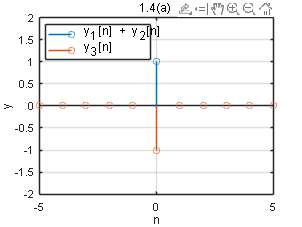

nx = -5:5;
x1 = (nx == 0);          % delta[n]
x2 = 2 * (nx == 0);      % 2delta[n]
x3 = x1 + x2;            % x3[n] = x1[n] + x2[n]

y1 = sin(pi/2 * x1);
y2 = sin(pi/2 * x2);
y3 = sin(pi/2 * x3);

% 验证线性叠加性：比较 y1 + y2 和 y3
y_sum = y1 + y2;

figure;
stem(nx, y_sum); 
hold on;
stem(nx, y3);
xlabel('n'); ylabel('y');
title('1.4(a) ');
legend('y_1[n] + y_2[n]', 'y_3[n]',Location='southeast');
ylim([-2,2])
grid on;

legend("Position", [0.16145,0.73547,0.3254,0.15669])

`(3)结果图`

`(4)结果分析`

y1[0] = sin(pi/2 * 1) = 1

y2[0] = sin(pi/2 * 2) = sin(pi) ≈ 0

y1[0] + y2[0] = 1

y3[0] = sin(pi/2 * 3) = sin(3pi/2) = -1

y1+y2 ≠ y3，不满足叠加性，所以系统是非线性的

`经验总结：`

`@朱泺源：`使用 (nx == 0) 构造单位冲激非常方便。画图时用 stem 并添加图例，可以直观地对比叠加前后的输出，从而快速判断系统是否线性。

`@罗玛：可以`用统一的时间轴 nx 来管理信号，避免索引混乱

`自我评分：`

`@朱泺源：10`

`@罗玛：10`